
numerator_coeffs = [1 -2 2];
zeros = roots(numerator_coeffs);
poles = [-2 -4 -5 -6];

sys = zpk(zeros, poles, 1)

sys =
 
      (s^2 - 2s + 2)
  -----------------------
  (s+2) (s+4) (s+5) (s+6)
 
Continuous-time zero/pole/gain model.



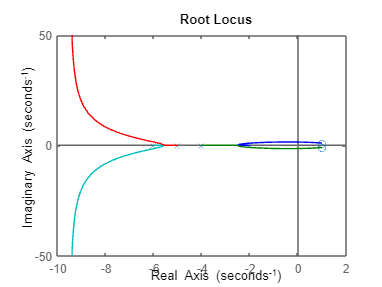

rlocus(sys)

G =
 
                1
  ------------------------------
  s^4 + 19 s^3 + 111 s^2 + 189 s
 
Continuous-time transfer function.



H =
 
       s + 30
  ----------------
  s^2 + 20 s + 225
 
Continuous-time transfer function.



sys2 =
 
                                                                                     
                              s^6 + 39 s^5 + 716 s^4 + 6684 s^3 + 28755 s^2 + 42525 s
                                                                                     
  ----------------------------------------------------------------------------------------------------------------
                                                                                                                  
  s^10 + 58 s^9 + 1568 s^8 + 24806 s^7 + 242598 s^6 + 1.466e06 s^5 + 5.263e06 s^4 + 1.015e07 s^3 + 8.034e06 s^2   
                                                                                                                  
                                                                                                          - 5670 s
                                                                                                                  
 
Continuous-time transfer function.



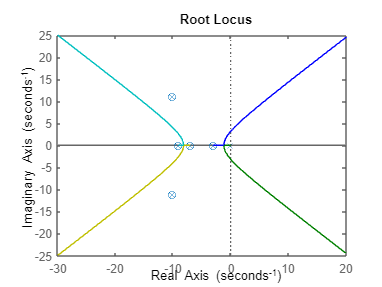

sisotool(sys)


syms s 

%eqn = (s + 30) + (s^2 + 20*s + 255)*(s*(s + 3)*(s + 7)*(s + 9))
eqn = s * (s + 3)*(s + 7)*(s + 9)*(s^2 + 20*s + 225) + (s + 30)

$$eqn = s+s\,\left(s+3\right)\,\left(s+7\right)\,\left(s+9\right)\,\left(s^{2}+20\,s+225\right)+30$$

expand(eqn)

$$ans = s^{6}+39\,s^{5}+716\,s^{4}+6684\,s^{3}+28755\,s^{2}+42526\,s+30$$

sys = tf([1], [1 39 746 7254 32085 48196 30])

sys =
 
                               1
  ------------------------------------------------------------
  s^6 + 39 s^5 + 746 s^4 + 7254 s^3 + 32085 s^2 + 48196 s + 30
 
Continuous-time transfer function.
Model Properties


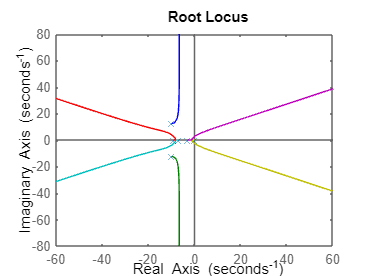


rlocus(sys)

sisotool(sys)

eqn = s * (s + 3)*(s + 7)*(s + 9);
expand(eqn)

$$ans = s^{4}+19\,s^{3}+111\,s^{2}+189\,s$$

G = tf(1, [1 19 111 189 0]);
H = tf([1 30], [1 20 225]);

T = (1/(1 + G*H))

T =
 
    s^6 + 39 s^5 + 716 s^4 + 6684 s^3 + 28755 s^2 + 42525 s
  ------------------------------------------------------------
  s^6 + 39 s^5 + 716 s^4 + 6684 s^3 + 28755 s^2 + 42526 s + 30
 
Continuous-time transfer function.
Model Properties



sisotool(T)